# Ground Truths Dataset 1

## Clear workspace and all figures

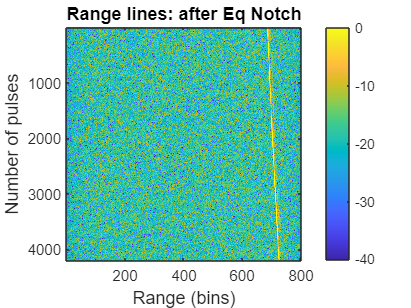


clear all;clc;close all

%% Load Data
[FileName,Path2RadarData,filter_index]=uigetfile('','Select Radar Dataset');
RadarData = load([Path2RadarData filesep FileName]);

%% Extract Range Profiles before, after Equalisation and after Notch filtering

RangeProfiles_BeforeEq = RadarData.RangeLines_BeforeEq;
RangeProfiles_AfterEq = RadarData.RangeLines_AfterEq;
RangeProfiles_AfterEqNotch = RadarData.RangeLines_AfterEQ_Notch;

%% Extract other radar parameters

 PRF_Hz = RadarData.Info.PRF_Hz;
 Bandwidth_Hz = RadarData.Info.Bandwidth_Hz;
 RangeStart_m = RadarData.Info.RangeStart_m;
 BlindRange_m = RadarData.Info.BlindRange_m;
 
[NumOfPulses,NumOfRangeBins]=size(RangeProfiles_AfterEqNotch);

%% Plot Range Profiles

fontsize1 = 12;
clims = [-40 0];

% Normalise data to have a peak of 0dB or 1 in linear scale
[MaxRangeLine MaxIdx] = max(max(abs(RangeProfiles_AfterEqNotch)));
MaxRangeLine = (1/3)*MaxRangeLine;

% Plot range lines
figure; axes('fontsize',fontsize1);
imagesc(20*log10(abs(RangeProfiles_AfterEqNotch)./MaxRangeLine),clims);
colorbar;
xlabel('Range (bins)','fontsize',fontsize1);
ylabel('Number of pulses','fontsize',fontsize1);
title('Range lines: after Eq Notch','fontsize',fontsize1);

## Detection Point Calculations for Dataset 3

%final variable of detection points
Target_locations_DS3 = zeros(NumOfPulses, NumOfRangeBins);

% Parameters for sections of data to screenshot
stepSize = 100;
numIterations = ceil(NumOfPulses/stepSize)

numIterations = 42

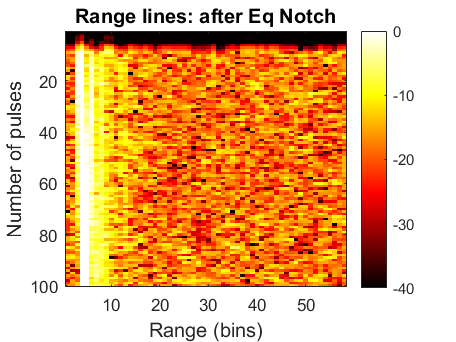

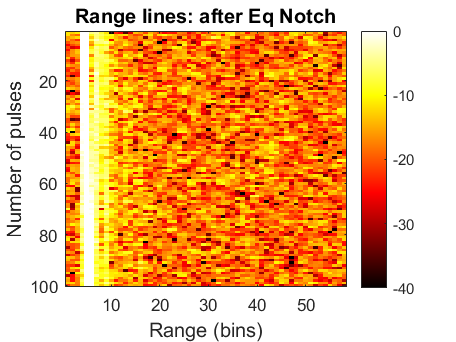

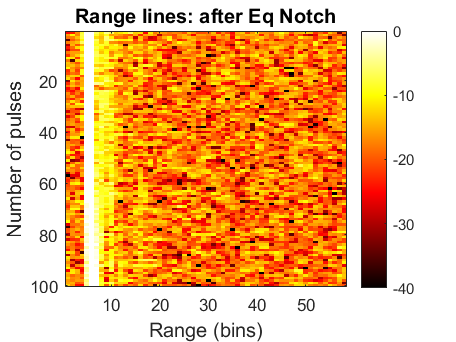

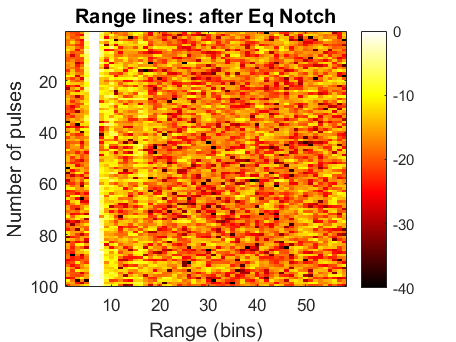

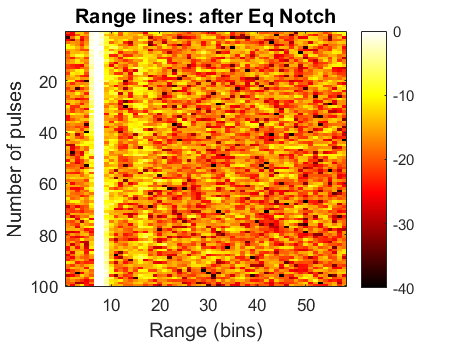

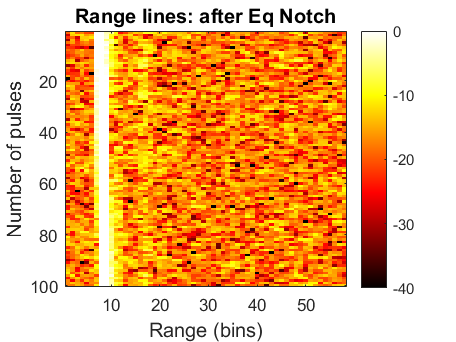

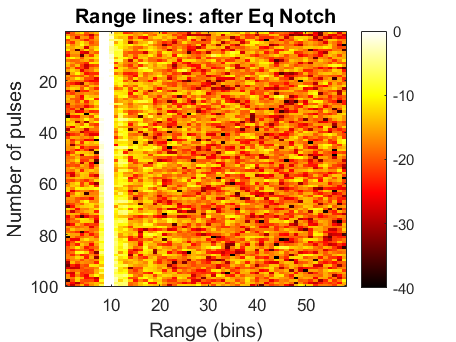

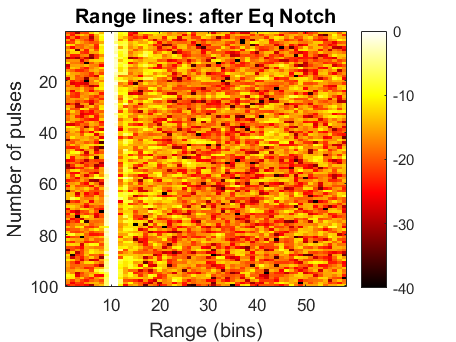


%loop to calculate detections per screenshotted section
for z = 1:numIterations
    if z <numIterations
    RangeProfiles = RangeProfiles_AfterEqNotch(1+stepSize*(z-1):stepSize*z,683:740);
    [NumOfPulses,NumOfRangeBins]=size(RangeProfiles);
    fontsize1 = 12;
    clims = [-40 0];
    
    % Plot range lines
    figure; axes('fontsize',fontsize1);
    imagesc(20*log10(abs(RangeProfiles)./MaxRangeLine),clims);
    colormap('hot');
    colorbar;
    xlabel('Range (bins)','fontsize',fontsize1);
    ylabel('Number of pulses','fontsize',fontsize1);
    title('Range lines: after Eq Notch','fontsize',fontsize1);
    
    % Get the current figure handl
    fig = gcf;
    frame = getframe(fig);
    % Convert the captured frame to an RGB image:
    rgb_image = frame.cdata;
    % Convert RGB image to HSV color space:
    hsv_image = rgb2hsv(rgb_image);
    hsv_image = hsv_image(41:466, 83:566, :);
    
    % Define hue and saturation thresholds for yellow:
    hue_threshold = [0, 0.9]; % Adjust as needed
    saturation_threshold = [0, 0.8]; % Adjust as needed

    % Create binary mask based on hue and saturation thresholds:
    target_pnts = (hsv_image(:,:,1) >= hue_threshold(1) & hsv_image(:,:,1) <= hue_threshold(2)) & ...
              (hsv_image(:,:,2) >= saturation_threshold(1) & hsv_image(:,:,2) <= saturation_threshold(2));
    

    target_pnts = double(target_pnts);
    [numtargetRows,numtargetCols] = size(target_pnts);
    
    target_pnts_resized = zeros(numtargetRows, NumOfRangeBins);
    for i = 1:numtargetRows
        targetsOriginalRowsize = 1:numel(target_pnts(i,:));
        targetsNewRowSize = linspace(1, numtargetCols, NumOfRangeBins);
        target_pnts_resized(i, :) = interp1(targetsOriginalRowsize, target_pnts(i,:), targetsNewRowSize, 'linear');
    end
    
    target_pnts_resized = abs(target_pnts_resized) ==1;
    target_pnts_resized = double(target_pnts_resized);
    finalTargetPnts = zeros(NumOfPulses, NumOfRangeBins); 
    
    for i = 1:NumOfRangeBins
        targetsOriginalColsize = 1:numel(target_pnts_resized(:,i));
        targetsNewRowSize = linspace(1, numtargetRows, NumOfPulses);
        finalTargetPnts(:, i) = interp1(targetsOriginalColsize, target_pnts_resized(:,i), targetsNewRowSize, 'linear');
    end
    
    finalTargetPnts = abs(finalTargetPnts) ==1;
    finalTargetPnts = double(finalTargetPnts);
    Target_locations_DS3(1+stepSize*(z-1):stepSize*z,683:740) = finalTargetPnts;





elseif z == numIterations
    RangeProfiles = RangeProfiles_AfterEqNotch(1+stepSize*(z-1):end,683:740);
    [NumOfPulses,NumOfRangeBins]=size(RangeProfiles);
    fontsize1 = 12;
    clims = [-40 0];
    
    % Plot range lines
    figure; axes('fontsize',fontsize1);
    imagesc(20*log10(abs(RangeProfiles)./MaxRangeLine),clims);
    colormap('hot');
    colorbar;
    xlabel('Range (bins)','fontsize',fontsize1);
    ylabel('Number of pulses','fontsize',fontsize1);
    title('Range lines: after Eq Notch','fontsize',fontsize1);
    
    % Get the current figure handl
    fig = gcf;
    frame = getframe(fig);
    % Convert the captured frame to an RGB image:
    rgb_image = frame.cdata;
    % Convert RGB image to HSV color space:
    hsv_image = rgb2hsv(rgb_image);
    hsv_image = hsv_image(41:466, 83:566, :);
    
    % Define hue and saturation thresholds for yellow:
    hue_threshold = [0, 0.9]; % Adjust as needed
    saturation_threshold = [0, 0.8]; % Adjust as needed

    % Create binary mask based on hue and saturation thresholds:
    target_pnts = (hsv_image(:,:,1) >= hue_threshold(1) & hsv_image(:,:,1) <= hue_threshold(2)) & ...
              (hsv_image(:,:,2) >= saturation_threshold(1) & hsv_image(:,:,2) <= saturation_threshold(2));
    
    target_pnts = double(target_pnts);
    [numtargetRows,numtargetCols] = size(target_pnts);
    
    target_pnts_resized = zeros(numtargetRows, NumOfRangeBins);
    for i = 1:numtargetRows
        targetsOriginalRowsize = 1:numel(target_pnts(i,:));
        targetsNewRowSize = linspace(1, numtargetCols, NumOfRangeBins);
        target_pnts_resized(i, :) = interp1(targetsOriginalRowsize, target_pnts(i,:), targetsNewRowSize, 'linear');
    end
    
    target_pnts_resized = abs(target_pnts_resized) ==1;
    target_pnts_resized = double(target_pnts_resized);
    finalTargetPnts = zeros(NumOfPulses, NumOfRangeBins); 
    
    for i = 1:NumOfRangeBins
        targetsOriginalColsize = 1:numel(target_pnts_resized(:,i));
        targetsNewRowSize = linspace(1, numtargetRows, NumOfPulses);
        finalTargetPnts(:, i) = interp1(targetsOriginalColsize, target_pnts_resized(:,i), targetsNewRowSize, 'linear');
    end
    
    finalTargetPnts = abs(finalTargetPnts) ==1;
    Target_locations_DS3(1+stepSize*(z-1):end,683:740) = finalTargetPnts; 
    end
end

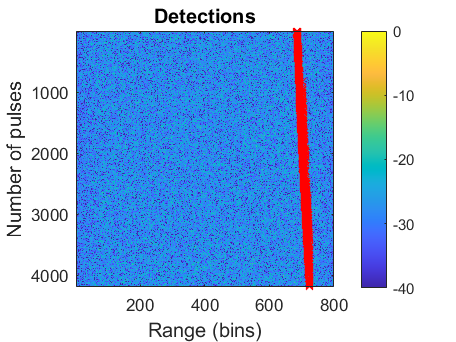



% Manual removal of noise data points registered as targets 
Target_locations_DS3(1:end, 683:684) = 0;
for p = 685:719
    Target_locations_DS3(((p-684)*120):end, p) = 0;
end

for p = 704:723
    Target_locations_DS3(((p-703)*100+2200):end, p) = 0;
end

for p = 701:740
    Target_locations_DS3(1:((p-701)*80+650), p) = 0;
end
for p = 690:701
    Target_locations_DS3(1:((p-689)*130), p) = 0;
end
for p = 701:730
    Target_locations_DS3(1:((p-701)*120+650), p) = 0;
end

    Target_locations_DS3(:, 727:end) = 0;

Target_locations_DS3(1716:1922, 711:715) = 0;
Target_locations_DS3(2382:2826, 719:722) = 0;
Target_locations_DS3(2862:3166, 724:727) = 0;
Target_locations_DS3(3683:3864, 732:740) = 0;


% % Save the dataset to a .mat file
save('Target_locations_DS3.mat', 'Target_locations_DS3');

%plot final ground truths
fontsize1 = 12;
[MaxRangeLine MaxIdx] = max(max(abs(RangeProfiles_AfterEqNotch)));
clims = [-40 0];
figure; axes('fontsize',fontsize1);
imagesc(20*log10(abs(RangeProfiles_AfterEqNotch)./MaxRangeLine),clims);
colorbar;
xlabel('Range (bins)','fontsize',fontsize1);
ylabel('Number of pulses','fontsize',fontsize1);
title('Detections','fontsize',fontsize1);
hold on

[pulseCoord, rangeCoord] = find(Target_locations_DS3 == 1);

% Plot 'x' at positions where matrix value is 1
scatter(rangeCoord, pulseCoord, 'rx');